# Practice 4 FFT

Author : Tzu-Chieh Hsu

**ECIE Copyright Reserved**

clear;
format shortEng

**Square wave **

f = 200e3;
D = 0.25;
Vs = 48;
ws = 2*pi*f;

Ts = 1/f;
cycle = 2;
t = 0:Ts/200:cycle*Ts;
tn = mod(t,Ts)

tn =      0.0000e+000    25.0000e-009    50.0000e-009    75.0000e-009   100.0000e-009   125.0000e-009   150.0000e-009   175.0000e-009   200.0000e-009   225.0000e-009   250.0000e-009   275.0000e-009   300.0000e-009   325.0000e-009   350.0000e-009   375.0000e-009   400.0000e-009   425.0000e-009   450.0000e-009   475.0000e-009   500.0000e-009   525.0000e-009   550.0000e-009   575.0000e-009   600.0000e-009   625.0000e-009   650.0000e-009   675.0000e-009   700.0000e-009   725.0000e-009   750.0000e-009   775.0000e-009   800.0000e-009   825.0000e-009   850.0000e-009   875.0000e-009   900.0000e-009   925.0000e-009   950.0000e-009   975.0000e-009     1.0000e-006     1.0250e-006     1.0500e-006     1.0750e-006     1.1000e-006     1.1250e-006     1.1500e-006     1.1750e-006     1.2000e-006     1.2250e-006


Manual generate square waveform.

(or you can generate by 'square' function.)

wave = zeros(size(t));
wave = wave + Vs.*(tn > 0 & tn <= D*Ts);
wave = wave + 0.*(tn > D*Ts & tn <= Ts);

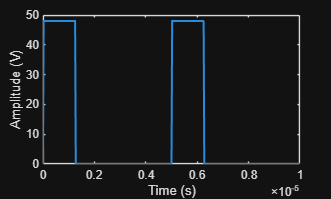

figure;
plot(t,wave, ...
    'LineWidth',1.5)

xlabel('Time (s)');
ylabel('Amplitude (V)');
xlim([min(t) max(t)])

## **Step 1 **

※ In textbook 

In the textbook, $c_n$ only has a real part and no imaginary part, so the correct angle cannot be obtained. In other words, $\theta_n$ cannot be derived from this formula.


$$x(t) = c_0 + \sum^\infty_{n=1}c_{n\_textbook}\sin(n\omega_st+\theta_n)$$



$$c_{n\_textbook} = |(c_n)| = \sqrt{a_n^2+(b_n)^2$$


※ Correct step

Let $A = Vs$

Form 1

    
$$a_n = \frac{A}{n\pi}\sin(2\pi nD)$$


    
$$b_n = \frac{A}{n\pi}(1-\cos(2\pi nD))$$


    
$$x(t) = a0 + \sum^{\infty}_{n=1}(a_ncos(\frac{2\pi nt}{T})+b_nsin(\frac{2\pi nt}{T}))$$


Form 2

    
$$c_0 = a_0$$
    

    
$$c_n = a_n-ib_n$$
    

    
$$x(t) = c0 + \sum^{\infty}_{n=1}c_ne^{\frac{2\pi int}{T}}$$


n_max = 10

n_max =     10.0000e+000


n_list = 1:1:n_max % First harmonic

n_list =      1.0000e+000     2.0000e+000     3.0000e+000     4.0000e+000     5.0000e+000     6.0000e+000     7.0000e+000     8.0000e+000     9.0000e+000    10.0000e+000



fn = [0 n_list].*f

fn =      0.0000e+000   200.0000e+003   400.0000e+003   600.0000e+003   800.0000e+003     1.0000e+006     1.2000e+006     1.4000e+006     1.6000e+006     1.8000e+006     2.0000e+006



a0 = D*Vs

a0 =     12.0000e+000


an = Vs ./ (n_list.*pi) .* sin(2.*n_list.*pi*D)

an =     15.2789e+000   935.5612e-018    -5.0930e+000  -935.5612e-018     3.0558e+000   935.5612e-018    -2.1827e+000  -935.5612e-018     1.6977e+000   935.5612e-018


bn = Vs ./ (n_list.*pi) .* (1-cos(2.*n_list.*pi.*D))

bn =     15.2789e+000    15.2789e+000     5.0930e+000     0.0000e+000     3.0558e+000     5.0930e+000     2.1827e+000     0.0000e+000     1.6977e+000     3.0558e+000



cn = (an - 1i.*bn)

cn =     15.2789e+000 - 15.2789e+000i   935.5612e-018 - 15.2789e+000i    -5.0930e+000 -  5.0930e+000i  -935.5612e-018 +  0.0000e+000i     3.0558e+000 -  3.0558e+000i   935.5612e-018 -  5.0930e+000i    -2.1827e+000 -  2.1827e+000i  -935.5612e-018 +  0.0000e+000i     1.6977e+000 -  1.6977e+000i   935.5612e-018 -  3.0558e+000i


c0  = a0;

Form 1   $x(t) = a0 + \sum^{\infty}_{n=1}(a_ncos(\frac{2\pi nt}{T})+b_nsin(\frac{2\pi nt}{T}))$

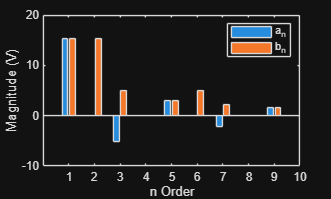

figure;

bar(n_list, [an;bn])
xlabel('n Order');
ylabel('Magnitude (V)');
legend('a_n','b_n')

xlim([0,10])

Form 2  $c_n = a_n-ib_n$   

**Bar Chart**

figure;
axes;
legend('Location','best')

hold on;

xlabel('n Order');
ylabel('Magnitude (V)');
legend();
xlim([-1,10])


table = readtable("./fft.txt")

table = 602×3 table
    Frequency      V_Vo_         V_Vx_   
    _________    __________    __________

          0           12.01         12.01
     3333.3           12.01         12.01
     6666.7      3.2244e-15    2.7472e-16
      10000      9.4553e-15    0.00013195
      13333      1.0594e-14    0.00026389
      16667      4.5087e-15    0.00013195
      20000      2.5408e-15    7.1663e-17
      23333      6.8373e-14     0.0011785
      26667      1.3411e-13      0.002357
      30000      6.8856e-14     0.0011785
      33333       3.038e-15    5.4312e-17
      36667      7.7534e-14    0.00034307
      40000      1.5242e-13    0.00068613
      43333      7.6446e-14    0.00034307
      46667      4.1785e-15     4.555e-16
      50000      9.6168e-15    0.00089543


freq = table.Frequency'

freq =      0.0000e+000     3.3333e+003     6.6667e+003    10.0000e+003    13.3333e+003    16.6667e+003    20.0000e+003    23.3333e+003    26.6667e+003    30.0000e+003    33.3333e+003    36.6667e+003    40.0000e+003    43.3333e+003    46.6667e+003    50.0000e+003    53.3333e+003    56.6667e+003    60.0000e+003    63.3333e+003    66.6667e+003    70.0000e+003    73.3333e+003    76.6667e+003    80.0000e+003    83.3333e+003    86.6667e+003    90.0000e+003    93.3333e+003    96.6667e+003   100.0000e+003   103.3333e+003   106.6667e+003   110.0000e+003   113.3333e+003   116.6667e+003   120.0000e+003   123.3333e+003   126.6667e+003   130.0000e+003   133.3333e+003   136.6667e+003   140.0000e+003   143.3333e+003   146.6667e+003   150.0000e+003   153.3333e+003   156.6667e+003   160.0000e+003   163.3333e+003


tol = 100

tol =    100.0000e+000


idx = find(any(abs(freq(:)' - fn(:)) < tol, 1))

idx =      1.0000e+000    61.0000e+000   121.0000e+000   181.0000e+000   241.0000e+000   301.0000e+000   361.0000e+000   421.0000e+000   481.0000e+000   541.0000e+000   601.0000e+000


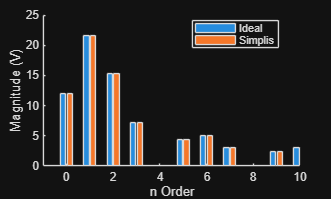


bar([0 n_list], [[c0 abs(cn)];table.V_Vx_(idx)'])
legend({'Ideal','Simplis'})

## **Step 2**

1.L = 40 * 10^-6 H

2.C = 470 * 10^-6 F

L = 10 * 10e-6;
C = 100 * 10e-6;

**Calculate the cutoff frequency of the filter**.

w0 = sqrt(1/(L*C))

w0 =      3.1623e+003


f0 = w0 / (2*pi)

f0 =    503.2921e+000


**Plot the Bode plot of the filter**.

Transfer function of LC filter

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


Glc = (1/(L*C)) / (s^2 + w0^2)


Glc =
 
     1e07
  ----------
  s^2 + 1e07
 
Continuous-time transfer function.


**Bode plot**

figure;
opts = bodeoptions;
opts.Title.String = 'LC Filter';
opts.FreqUnits = 'Hz';

bodeplot(Glc,opts,{2*pi*1,2*pi*1e6})

ax_amp = gcf().Children(1);
ax_phs = gcf().Children(1);

grid on;

**Get gain and phase**

resp = freqresp(Glc, 2*pi*f);
gain = mag2db(abs(resp))

gain =   -103.9683e+000


phase = rad2deg(angle(resp))

phase =    180.0000e+000


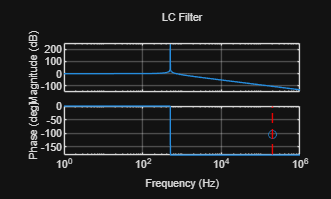


xline(ax_amp,f,'--r');  % '--r' 
xline(ax_phs,f,'--r');  % '--r' 

hold(ax_amp,"on");
hold(ax_phs,"on");
semilogx(ax_amp,f,gain,'-o')

resp = freqresp(Glc, n_list .* f .* (2*pi));
cn_filter = cn .* (squeeze(resp))'; 

**Bar Chart**

figure;
axes;
legend('Location','best')

hold on;

xlabel('n Order');
ylabel('Magnitude (V)');
legend();
xlim([-1,10])


table = readtable("./fft.txt")

table = 602×3 table
    Frequency      V_Vo_         V_Vx_   
    _________    __________    __________

          0           12.01         12.01
     3333.3           12.01         12.01
     6666.7      3.2244e-15    2.7472e-16
      10000      9.4553e-15    0.00013195
      13333      1.0594e-14    0.00026389
      16667      4.5087e-15    0.00013195
      20000      2.5408e-15    7.1663e-17
      23333      6.8373e-14     0.0011785
      26667      1.3411e-13      0.002357
      30000      6.8856e-14     0.0011785
      33333       3.038e-15    5.4312e-17
      36667      7.7534e-14    0.00034307
      40000      1.5242e-13    0.00068613
      43333      7.6446e-14    0.00034307
      46667      4.1785e-15     4.555e-16
      50000      9.6168e-15    0.00089543


freq = table.Frequency'

freq =      0.0000e+000     3.3333e+003     6.6667e+003    10.0000e+003    13.3333e+003    16.6667e+003    20.0000e+003    23.3333e+003    26.6667e+003    30.0000e+003    33.3333e+003    36.6667e+003    40.0000e+003    43.3333e+003    46.6667e+003    50.0000e+003    53.3333e+003    56.6667e+003    60.0000e+003    63.3333e+003    66.6667e+003    70.0000e+003    73.3333e+003    76.6667e+003    80.0000e+003    83.3333e+003    86.6667e+003    90.0000e+003    93.3333e+003    96.6667e+003   100.0000e+003   103.3333e+003   106.6667e+003   110.0000e+003   113.3333e+003   116.6667e+003   120.0000e+003   123.3333e+003   126.6667e+003   130.0000e+003   133.3333e+003   136.6667e+003   140.0000e+003   143.3333e+003   146.6667e+003   150.0000e+003   153.3333e+003   156.6667e+003   160.0000e+003   163.3333e+003


tol = 100

tol =    100.0000e+000


idx = find(any(abs(freq(:)' - fn(:)) < tol, 1))

idx =      1.0000e+000    61.0000e+000   121.0000e+000   181.0000e+000   241.0000e+000   301.0000e+000   361.0000e+000   421.0000e+000   481.0000e+000   541.0000e+000   601.0000e+000


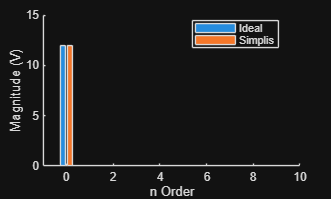


bar([0 n_list], [[c0 abs(cn_filter)]; table.V_Vo_(idx)'])
legend({'Ideal','Simplis'})